# Power generation and Energy Budget

## A. Power Generated with other pointings pointing Vs Beta angle at an altitude

### 1. Calculation at multiple altitudes, case for orbital pointing mode

First, we will see what is the generated power at different altitudes, with the variation of the beta angle.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 1 in this section, because it corresponds to the orbital (nadir) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 1;   %"sun-aero" pointing mode
% 1: "orbital" Reference quaternion is aligned with ORF. 
% 2: "sun-aero" Reference quaternion is such that x is aligned with velocity and z is aligned as best as possible with the sun direction to maximize the power generation 
% 3: "sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction. 
% 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 90° along the y axis, therefore, the reference quaternion is an attitude for maximizing the drag surface. 
% 5: "retrogade firing" Reference quaternion is similar than in Case 1, but rotated 180° along the z axis, therefore, the reference quaternion is an attitude for retrograde propulsion. (??should be like case 2 but rotated?)
% 6: Reference quaternion is static [1 0 0 0], but this time is the only case where the state of the B-dot is enabled (1). 
% 7: Reference quaternion is a custom quaternion that has to be defined by the user as an input to the mission block. 
% 8: "sun-drag" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the nadir direction.

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_nadir(j,i)=mean(Pcollected);
        B_nadir(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode1.mat','B_nadir','Pav_nadir')  
        %load('power_from_b_alt_mode1.mat') %if we don't want to run the whole simulation again
        Pav=Pav_nadir;
        B=B_nadir;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

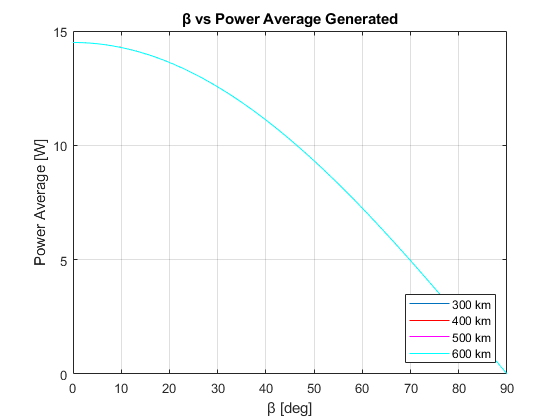

%Pav1=10:0.1:40;
Pav1=0:0.1:15;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

figure(1)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

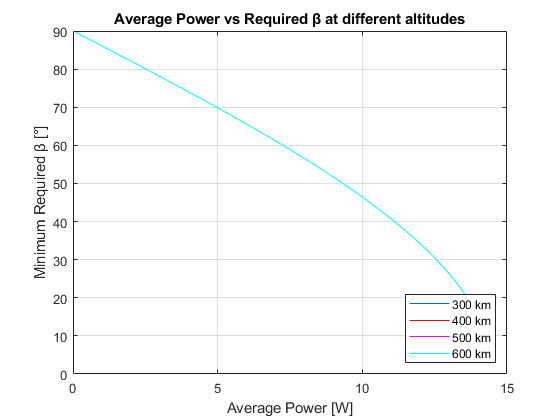

figure(2)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Minimum Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed

### 2. Calculation at multiple altitudes, case for sun-aero pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun-aero pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 2 in this section, because it corresponds to the sun-aero pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 2;   %"sun-aero" pointing mode

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode2.mat','B','Pav')  
        load('power_from_b_alt_mode2.mat') %if we don't want to run the whole simulation again
        Pav = Pav_saero;
        B = B_saero;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

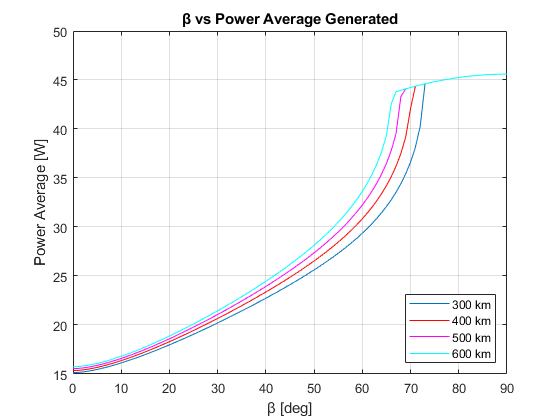

Pav1=10:0.1:40;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

close all

figure(3)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

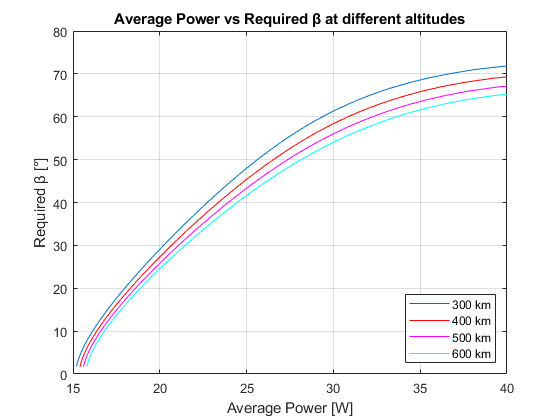

figure(4)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 3. Calculation at multiple altitudes, case for sun pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 3 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 3;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sun(j,i)=mean(Pcollected);
        B_sun(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode3.mat','B_sun','Pav_sun')  
        %load('power_from_b_alt_mode3.mat') %if we don't want to run the whole simulation again
        Pav = Pav_sun;
        B = B_sun;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

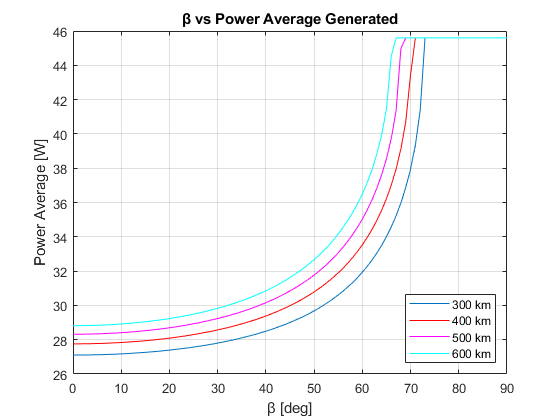

close all

figure(5)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

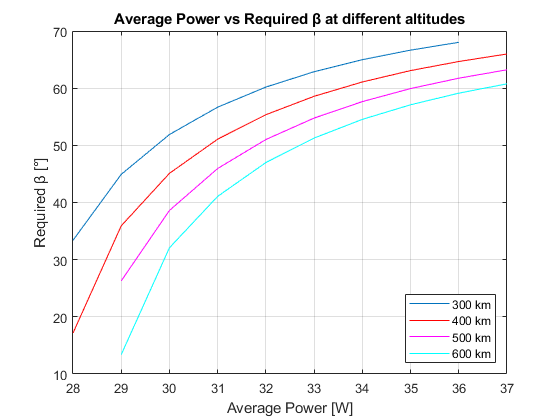

Pav1=28:1:45;
%Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,1:70),B(1,1:70),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,1:65),B(3,1:65),Pav1);
B4 = interp1(Pav(4,2:62),B(4,2:62),Pav1);

figure(6)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 5. Calculation at multiple altitudes, case for sun-drag pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun-drag pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 8 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 8;   %"aero-drag" pointing mode

for j=1:1
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_drag(j,i)=mean(Pcollected);
        B_drag(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode4.mat','B','Pav')  
        %load('power_from_b_alt_mode4.mat') %if we don't want to run the whole simulation again
        Pav = Pav_drag;
        B = B_drag;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

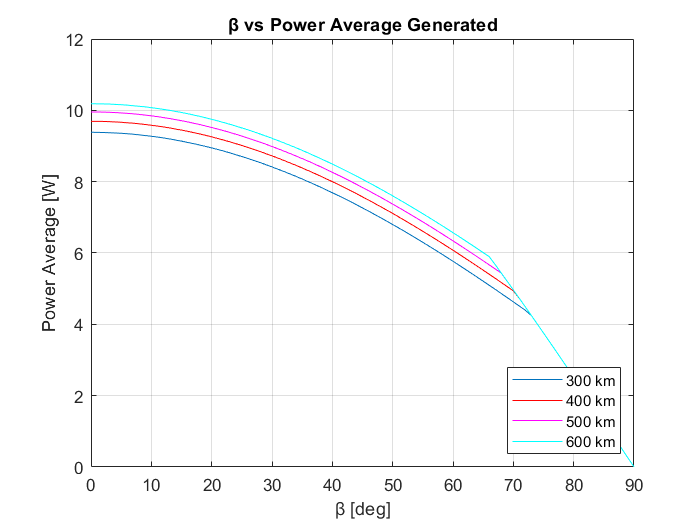

%Pav1=10:0.1:40;
Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

close all

figure(7)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

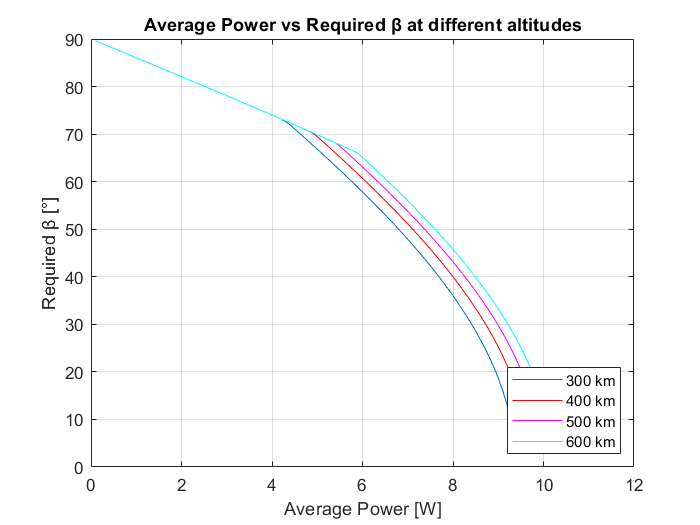

figure(8)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 4. Calculation at multiple altitudes, case for aero-drag pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the aero-drag pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 1 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 4;   %"aero-drag" pointing mode

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_drag(j,i)=mean(Pcollected);
        B_drag(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode4.mat','B_drag','Pav_drag')  
        %load('power_from_b_alt_mode4.mat') %if we don't want to run the whole simulation again
        Pav = Pav_drag;
        B = B_drag;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

%Pav1=10:0.1:40;
Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

close all

figure(7)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

figure(8)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 5. Calculation at multiple altitudes, case for sun-drag pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun-drag pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 8 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 8;   %"sun-drag" pointing mode
% 8: "sun-drag" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the nadir direction.

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sundrag(j,i)=mean(Pcollected);
        B_sundrag(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode8.mat','B_sundrag','Pav_sundrag')  
        %load('power_from_b_alt_mode8.mat') %if we don't want to run the whole simulation again
        Pav = Pav_sundrag;
        B = B_sundrag;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

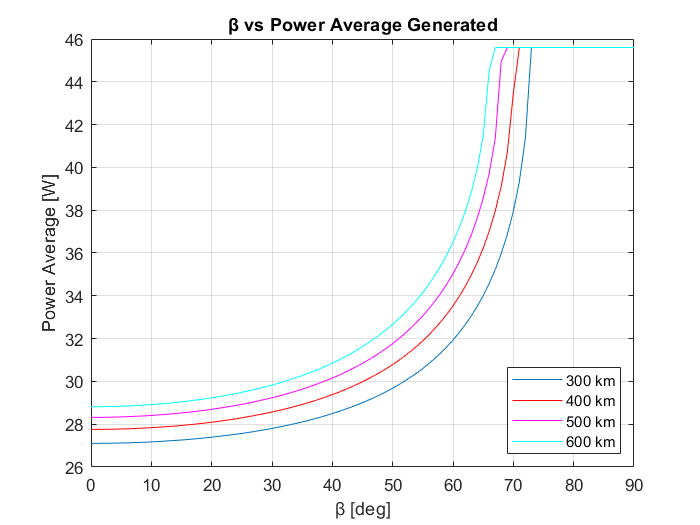

%Pav1=10:0.1:40;
% Pav1=0:0.1:10.5;
% B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
% B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
% B3 = interp1(Pav(3,:),B(3,:),Pav1);
% B4 = interp1(Pav(4,:),B(4,:),Pav1);
Pav1=28:1:45;
%Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,4:72),B(1,4:72),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,1:65),B(3,1:65),Pav1);
B4 = interp1(Pav(4,2:62),B(4,2:62),Pav1);

close all

figure(9)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

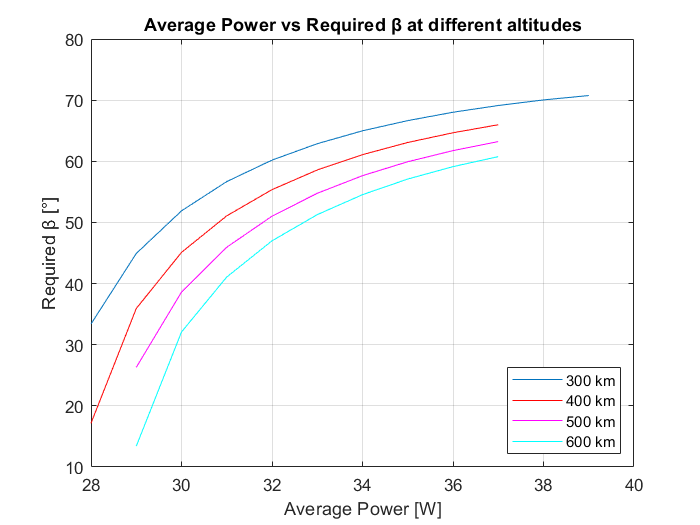

figure(10)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the results are practically the same as from case 3. The only difference is that in this case, the +X face will point toward nadir as much as it can.

## B. Calculation of the power generation during the descent phase

During the descent phase, the satellite will start descending, if the satellite is above 400km, then, the "retrograde propulsion" is used, from the point of view of power generation, this generates the same amount of power than the "sun-aero" attitude mode (it is only a rotation of 180 degrees of this attitude).

When the satellite reaches 400km, the aerodynamic drag is important and it is more effective to change the attitude pointing mode to the "aero-brake" pointing mode to maximize the surface of the satellite exposed to the atmosphere. In this pointing mode, the power is insufficient for large beta angles, the opposite case as for the other pointing modes (except the first one). We can see the comparison of both power generatio curves:

clear all
close all
load('power_from_b_alt_mode4.mat') %load parameters aero-drag
load('power_from_b_alt_mode8.mat') %load parameters sun-drag

We can plot and compare both power generation:

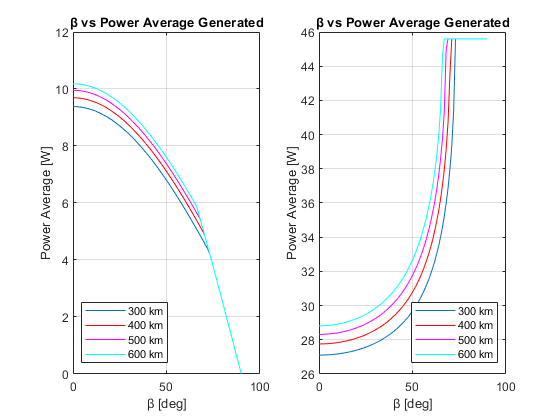

figure(11)
set(gcf,'color','w');
subplot(1,2,1)
        plot(B_drag(1,:),Pav_drag(1,:))
        hold on;
        plot(B_drag(2,:),Pav_drag(2,:),'r')
        plot(B_drag(3,:),Pav_drag(3,:),'m')
        plot(B_drag(4,:),Pav_drag(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southwest')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 
subplot(1,2,2)
        plot(B_sundrag(1,:),Pav_sundrag(1,:))
        hold on;
        plot(B_sundrag(2,:),Pav_sundrag(2,:),'r')
        plot(B_sundrag(3,:),Pav_sundrag(3,:),'m')
        plot(B_sundrag(4,:),Pav_sundrag(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

As seen from the previous plot, for lower values of beta angle, the aero-drag generates more power. The opposite is true for the sun-drag attitude.

Since the beta angles are expected to be in the ranges of large values, rather than low values, using the aero-drag mode would mean generating very low power, perhaps insufficient for the platform. The solution to this problem would be to change from one pointing mode to the other when the batteries reach a low value. So, let's see what would be the average power generation if it is possible to switch from one mode to the other, each one at a certain period of time, then averaging the power generation.

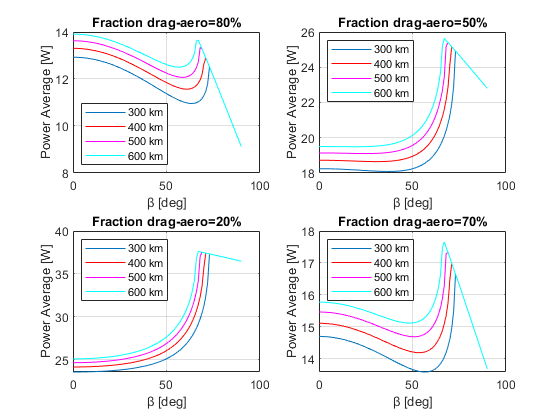

frac_aero=[80 50 20 70];
Pav_descent1=Pav_drag*frac_aero(1)/100+Pav_sundrag*(1-frac_aero(1)/100);
Pav_descent2=Pav_drag*frac_aero(2)/100+Pav_sundrag*(1-frac_aero(2)/100);
Pav_descent3=Pav_drag*frac_aero(3)/100+Pav_sundrag*(1-frac_aero(3)/100);
Pav_descent4=Pav_drag*frac_aero(4)/100+Pav_sundrag*(1-frac_aero(4)/100);
figure(12)
set(gcf,'color','w');
subplot(2,2,1)
        plot(B_drag(1,:),Pav_descent1(1,:))
        hold on;
        plot(B_drag(2,:),Pav_descent1(2,:),'r')
        plot(B_drag(3,:),Pav_descent1(3,:),'m')
        plot(B_drag(4,:),Pav_descent1(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southwest')
        title(['Fraction drag-aero=',num2str(frac_aero(1)), '%'])
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 
subplot(2,2,2)
        plot(B_drag(1,:),Pav_descent2(1,:))
        hold on;
        plot(B_drag(2,:),Pav_descent2(2,:),'r')
        plot(B_drag(3,:),Pav_descent2(3,:),'m')
        plot(B_drag(4,:),Pav_descent2(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','northwest')
        title(['Fraction drag-aero=',num2str(frac_aero(2)), '%'])
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 
subplot(2,2,3)
        plot(B_drag(1,:),Pav_descent3(1,:))
        hold on;
        plot(B_drag(2,:),Pav_descent3(2,:),'r')
        plot(B_drag(3,:),Pav_descent3(3,:),'m')
        plot(B_drag(4,:),Pav_descent3(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','northwest')
        title(['Fraction drag-aero=',num2str(frac_aero(3)), '%'])
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 
subplot(2,2,4)
        plot(B_drag(1,:),Pav_descent4(1,:))
        hold on;
        plot(B_drag(2,:),Pav_descent4(2,:),'r')
        plot(B_drag(3,:),Pav_descent4(3,:),'m')
        plot(B_drag(4,:),Pav_descent4(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','northwest')
        title(['Fraction drag-aero=',num2str(frac_aero(4)), '%'])
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 